## Load DataTable00

DataTable00 = getDataTable00('G1');
rois = {...
    'HippA';
    'HippP';
    'Ent';
    'MPFC';
    'Vis';
    };

## Mdl00a

formula00a = 'zTemplate ~ hemisphere + colocation + cpNonc + (1|subjectId)';
Mdl00a = fitRoiLmes(rois,formula00a,DataTable00);
disp(Mdl00a.FFX.tests);

                     (Intercept)                         cpNonc                         hemisphere                       colocation         
             ____________________________    ______________________________    _____________________________    ____________________________

    HippA    "t(120) = 1.02, p = 0.311;"     "t(120) = 0.854, p = 0.395;"      "t(120) = 0.269, p = 0.788;"     "t(120) = 0.35, p = 0.727;" 
    HippP    "t(120) = 1.89, p = 0.0609;"    "t(120) = 1.06, p = 0.293;"       "t(120) = 0.103, p = 0.918;"     "t(120) = 2.04, p = 0.0439;"
    Ent      "t(120) = 0.918, p = 0.36;"     "t(120) = -0.0495, p = 0.961;"    "t(120) = 0.0472, p = 0.962;"    "t(120) = 1.84, p = 0.0676;"
    MPFC     "t(120) = 0.732, p = 0.466;"    "t(120) = 0.864, p = 0.389;"      "t(120) = -

## Mdl00b

formula00b = 'zTemplate ~ hemisphere * colocation * cpNonc + (1|subjectId)';
Mdl00b = fitRoiLmes(rois,formula00b,DataTable00);
disp(Mdl00b.FFX.tests);

                     (Intercept)                         cpNonc                         hemisphere                       colocation                  cpNonc:hemisphere                cpNonc:colocation              hemisphere:colocation        cpNonc:hemisphere:colocation 
             ____________________________    ______________________________    _____________________________    ____________________________    ____________________________    ______________________________    ____________________________    _____________________________

    HippA    "t(116) = 1.02, p = 0.311;"     "t(116) = 0.854, p = 0.395;"      "t(116) = 0.289, p = 0.773;"     "t(116) = 0.376, p = 0.707;"    "t(116) = -1.4, p = 0.

[mC] = crrctdPtabel(Mdl00b);
disp(mC);

             (Intercept)    (Intercept)_alpha    cpNonc     cpNonc_alpha    hemisphere    hemisphere_alpha    colocation    colocation_alpha    cpNonc:hemisphere    cpNonc:hemisphere_alpha    cpNonc:colocation    cpNonc:colocation_alpha    hemisphere:colocation    hemisphere:colocation_alpha    cpNonc:hemisphere:colocation    cpNonc:hemisphere:colocation_alpha
             ___________    _________________    _______    ____________    __________    ________________    __________    ________________    _________________    _______________________    

## Plot: Anterior hippocampus

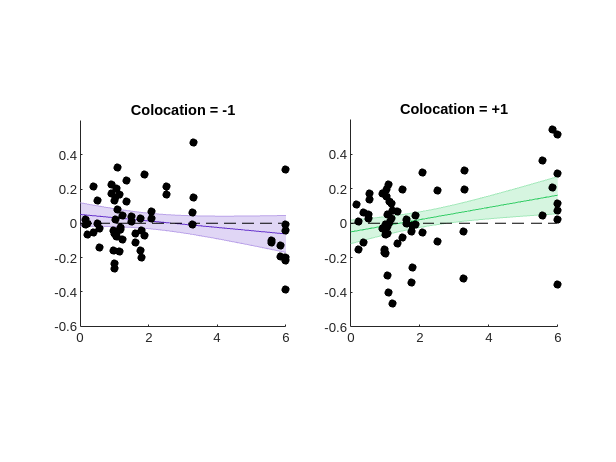

cDT = DataTable00(...
    contains(cellstr(DataTable00.roiName),'HippA'),:);
mu = mean(cDT.pNonc);
x = linspace(0,6,144);
figure;
subplot(1,2,1);
[~,y,low,upp] = getXEUL(Mdl00b.mdl.mdl{1},...
    1,x-mu,0,-1);
shadedErrorBar(x',y',[upp'-y';y'-low'],...
    'lineprops',{'Color',[0.4,0.2,0.8]});
hold on;
s = cDT.colocation==-1;
scatter(cDT.pNonc(s),cDT.zTemplate(s),30,'k','filled');
line([0,6],[0,0],'Color','k','LineStyle','--');
ylim([-0.6,0.6]);
axis square;
title('Colocation = -1');

subplot(1,2,2);
[~,y,low,upp] = getXEUL(Mdl00b.mdl.mdl{1},...
    1,x-mu,0,+1);
shadedErrorBar(x',y',[upp'-y';y'-low'],...
    'lineprops',{'Color',[0.2,0.8,0.4]});
hold on;
s = cDT.colocation==+1;
scatter(cDT.pNonc(s),cDT.zTemplate(s),30,'k','filled');
line([0,6],[0,0],'Color','k','LineStyle','--');
ylim([-0.6,0.6]);
axis square;
title('Colocation = +1');

## Plot: Entorhinal cortex

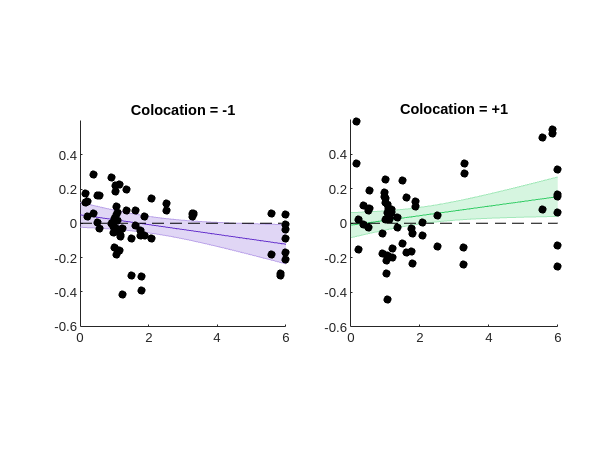

cDT = DataTable00(...
    contains(cellstr(DataTable00.roiName),'Ent'),:);
mu = mean(cDT.pNonc);
x = linspace(0,6,144);
figure;
subplot(1,2,1);
[~,y,low,upp] = getXEUL(Mdl00b.mdl.mdl{3},...
    1,x-mu,0,-1);
shadedErrorBar(x',y',[upp'-y';y'-low'],...
    'lineprops',{'Color',[0.4,0.2,0.8]});
hold on;
s = cDT.colocation==-1;
scatter(cDT.pNonc(s),cDT.zTemplate(s),30,'k','filled');
line([0,6],[0,0],'Color','k','LineStyle','--');
ylim([-0.6,0.6]);
axis square;
title('Colocation = -1');

subplot(1,2,2);
[~,y,low,upp] = getXEUL(Mdl00b.mdl.mdl{3},...
    1,x-mu,0,+1);
shadedErrorBar(x',y',[upp'-y';y'-low'],...
    'lineprops',{'Color',[0.2,0.8,0.4]});
hold on;
s = cDT.colocation==+1;
scatter(cDT.pNonc(s),cDT.zTemplate(s),30,'k','filled');
line([0,6],[0,0],'Color','k','LineStyle','--');
ylim([-0.6,0.6]);
axis square;
title('Colocation = +1');

## Plot: Posterior Hippocampus

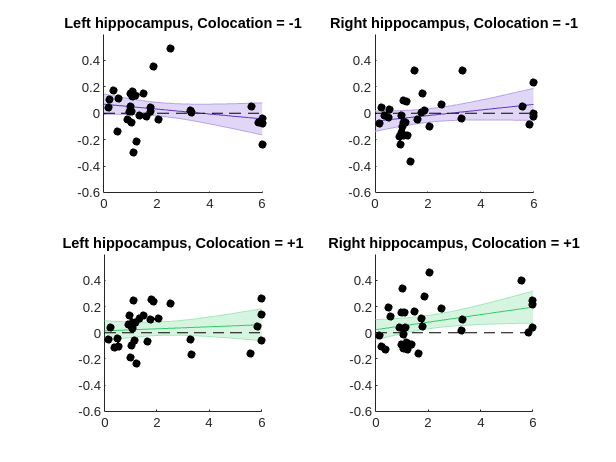

cDT = DataTable00(...
    contains(cellstr(DataTable00.roiName),'HippP'),:);
mu = mean(cDT.pNonc);
x = linspace(0,6,144);
figure;

subplot(2,2,1);
[~,y,low,upp] = getXEUL(Mdl00b.mdl.mdl{2},...
    1,x-mu,-1,-1);
shadedErrorBar(x',y',[upp'-y';y'-low'],...
    'lineprops',{'Color',[0.4,0.2,0.8]});
hold on;
s = cDT.colocation==-1 & cDT.hemisphere==-1;
scatter(cDT.pNonc(s),cDT.zTemplate(s),30,'k','filled');
line([0,6],[0,0],'Color','k','LineStyle','--');
ylim([-0.6,0.6]);
axis square;
title('Left hippocampus, Colocation = -1');

subplot(2,2,3);
[~,y,low,upp] = getXEUL(Mdl00b.mdl.mdl{2},...
    1,x-mu,-1,+1);
shadedErrorBar(x',y',[upp'-y';y'-low'],...
    'lineprops',{'Color',[0.2,0.8,0.4]});
hold on;
s = cDT.colocation==+1 & cDT.hemisphere==-1;
scatter(cDT.pNonc(s),cDT.zTemplate(s),30,'k','filled');
line([0,6],[0,0],'Color','k','LineStyle','--');
ylim([-0.6,0.6]);
axis square;
title('Left hippocampus, Colocation = +1');

subplot(2,2,2);
[~,y,low,upp] = getXEUL(Mdl00b.mdl.mdl{2},...
    1,x-mu,+1,-1);
shadedErrorBar(x',y',[upp'-y';y'-low'],...
    'lineprops',{'Color',[0.4,0.2,0.8]});
hold on;
s = cDT.colocation==-1 & cDT.hemisphere==+1;
scatter(cDT.pNonc(s),cDT.zTemplate(s),30,'k','filled');
line([0,6],[0,0],'Color','k','LineStyle','--');
ylim([-0.6,0.6]);
axis square;
title('Right hippocampus, Colocation = -1');

subplot(2,2,4);
[~,y,low,upp] = getXEUL(Mdl00b.mdl.mdl{2},...
    1,x-mu,+1,+1);
shadedErrorBar(x',y',[upp'-y';y'-low'],...
    'lineprops',{'Color',[0.2,0.8,0.4]});
hold on;
s = cDT.colocation==+1 & cDT.hemisphere==+1;
scatter(cDT.pNonc(s),cDT.zTemplate(s),30,'k','filled');
line([0,6],[0,0],'Color','k','LineStyle','--');
ylim([-0.6,0.6]);
axis square;
title('Right hippocampus, Colocation = +1');

## MDS + Heatmaps: Anterior hippocampus, colocation=+1

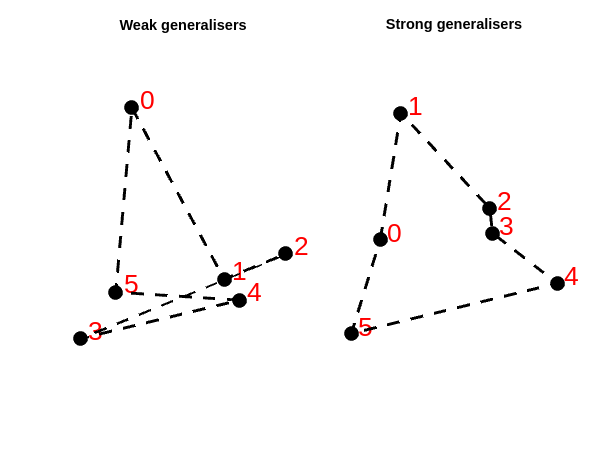

cDT = DataTable00(...
    contains(cellstr(DataTable00.roiName),'HippA') & ...
    DataTable00.colocation==+1,:);
wd = pwd;
cd ..
subjectIds = getSubjectIds('G1');
sIds_S = getSubjectIds('G2');
cd(wd);
sIds_W = subjectIds(~ismember(subjectIds,sIds_S));
Z_S = nan(6,6,numel(sIds_S));
Z_W = nan(6,6,numel(sIds_W));
iiS = 0;
iiW = 0;
for iSubject = 1:numel(subjectIds)
    cZ = cDT.patternSim(cDT.subjectId==subjectIds(iSubject));
    cZ = cellfun(@(M)(M+M')/2,cZ,'UniformOutput',false);
    cZ = mean(cell2mat(reshape(cZ,1,1,2)),3);
    cZ(logical(eye(6))) = Inf;
    switch ismember(subjectIds(iSubject),sIds_S)
        case true
            iiS = iiS + 1;
            Z_S(:,:,iiS) = cZ;
        case false
            iiW = iiW + 1;
            Z_W(:,:,iiW) = cZ;
    end
end

figure;

subplot(1,2,1);
hold on;
Z_W = mean(Z_W,3);
D = 1-tanh(Z_W);
xy = cmdscale(D,2);
scatter(xy(:,1),xy(:,2),100,'k','filled','o');
text(xy(:,1)+0.02,xy(:,2)+0.02,...
    cellfun(@num2str,num2cell((0:5)'),'UniformOutput',false),...
    'Color','red','FontSize',18);
line([xy(:,1);xy(1,1)],[xy(:,2);xy(1,2)],...
    'Color','k','LineStyle','--','LineWidth',2);
axis equal;
axis off;
title('Weak generalisers');

subplot(1,2,2);
hold on;
Z_S = mean(Z_S,3);
D = 1-tanh(Z_S);
xy = cmdscale(D,2);
%xy = tsne(D,'Distance','correlation','NumDimensions',2);
scatter(xy(:,1),xy(:,2),100,'k','filled','o');
text(xy(:,1)+0.02,xy(:,2)+0.02,...
    cellfun(@num2str,num2cell((0:5)'),'UniformOutput',false),...
    'Color','red','FontSize',18);
line([xy(:,1);xy(1,1)],[xy(:,2);xy(1,2)],...
    'Color','k','LineStyle','--','LineWidth',2);
axis equal;
axis off;
title('Strong generalisers');

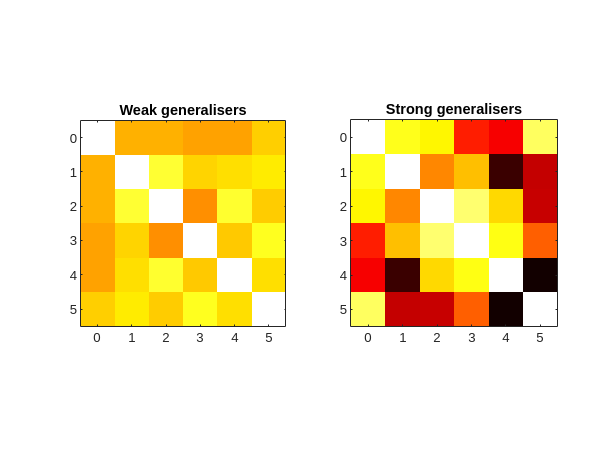

figure;
subplot(1,2,1);
h = imagesc(Z_W);
clim([0.3 0.4]);
colormap hot;
axis equal tight;
set(gca,'XTick',1:6,'YTick',1:6);
title('Weak generalisers');
xticklabels(cellfun(@num2str,num2cell(0:5),'UniformOutput',false));
yticklabels(cellfun(@num2str,num2cell(0:5),'UniformOutput',false));
subplot(1,2,2);
imagesc(Z_S);
clim([0.3 0.4]);
colormap hot;
axis equal tight;
set(gca,'XTick',1:6,'YTick',1:6);
xticklabels(cellfun(@num2str,num2cell(0:5),'UniformOutput',false));
yticklabels(cellfun(@num2str,num2cell(0:5),'UniformOutput',false));
title('Strong generalisers');

## MDS + Heatmaps: Entorhinal cortex, colocation=+1

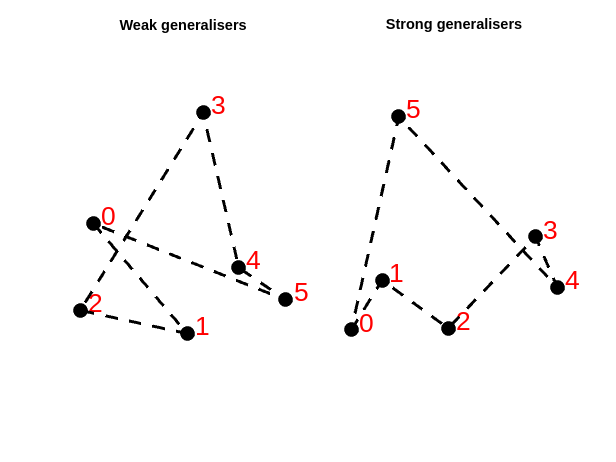

cDT = DataTable00(...
    contains(cellstr(DataTable00.roiName),'Ent') & ...
    DataTable00.colocation==+1,:);
wd = pwd;
cd ..;
subjectIds = getSubjectIds('G1');
sIds_S = getSubjectIds('G2');
cd(wd);
sIds_W = subjectIds(~ismember(subjectIds,sIds_S));
Z_S = nan(6,6,numel(sIds_S));
Z_W = nan(6,6,numel(sIds_W));
iiS = 0;
iiW = 0;
for iSubject = 1:numel(subjectIds)
    cZ = cDT.patternSim(cDT.subjectId==subjectIds(iSubject));
    cZ = cellfun(@(M)(M+M')/2,cZ,'UniformOutput',false);
    cZ = mean(cell2mat(reshape(cZ,1,1,2)),3);
    cZ(logical(eye(6))) = Inf;
    switch ismember(subjectIds(iSubject),sIds_S)
        case true
            iiS = iiS + 1;
            Z_S(:,:,iiS) = cZ;
        case false
            iiW = iiW + 1;
            Z_W(:,:,iiW) = cZ;
    end
end

figure;

subplot(1,2,1);
hold on;
Z_W = mean(Z_W,3);
D = 1-tanh(Z_W);
xy = cmdscale(D,2);
%xy = tsne(D,'Distance','correlation','NumDimensions',2);
scatter(xy(:,1),xy(:,2),100,'k','filled','o');
text(xy(:,1)+0.02,xy(:,2)+0.02,...
    cellfun(@num2str,num2cell((0:5)'),'UniformOutput',false),...
    'Color','red','FontSize',18);
line([xy(:,1);xy(1,1)],[xy(:,2);xy(1,2)],...
    'Color','k','LineStyle','--','LineWidth',2);
axis equal;
axis off;
title('Weak generalisers');

subplot(1,2,2);
hold on;
Z_S = mean(Z_S,3);
D = 1-tanh(Z_S);
xy = cmdscale(D,2);
scatter(xy(:,1),xy(:,2),100,'k','filled','o');
text(xy(:,1)+0.02,xy(:,2)+0.02,...
    cellfun(@num2str,num2cell((0:5)'),'UniformOutput',false),...
    'Color','red','FontSize',18);
line([xy(:,1);xy(1,1)],[xy(:,2);xy(1,2)],...
    'Color','k','LineStyle','--','LineWidth',2);
axis equal;
axis off;
title('Strong generalisers');

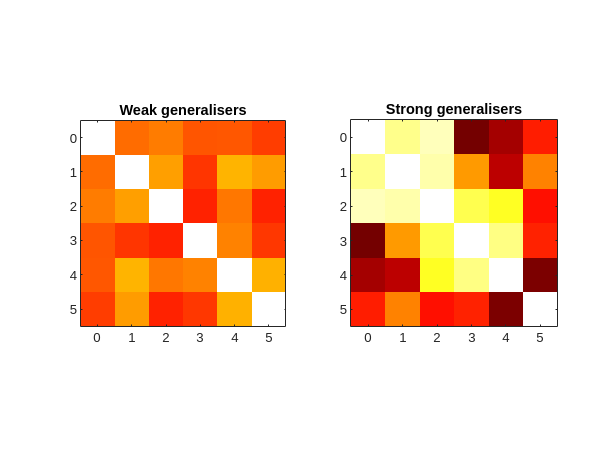

figure;
subplot(1,2,1);
h = imagesc(Z_W);
clim([0.3 0.4]);
colormap hot;
axis equal tight;
set(gca,'XTick',1:6,'YTick',1:6);
title('Weak generalisers');
xticklabels(cellfun(@num2str,num2cell(0:5),'UniformOutput',false));
yticklabels(cellfun(@num2str,num2cell(0:5),'UniformOutput',false));
subplot(1,2,2);
imagesc(Z_S);
clim([0.3 0.4]);
colormap hot;
axis equal tight;
set(gca,'XTick',1:6,'YTick',1:6);
xticklabels(cellfun(@num2str,num2cell(0:5),'UniformOutput',false));
yticklabels(cellfun(@num2str,num2cell(0:5),'UniformOutput',false));
title('Strong generalisers');